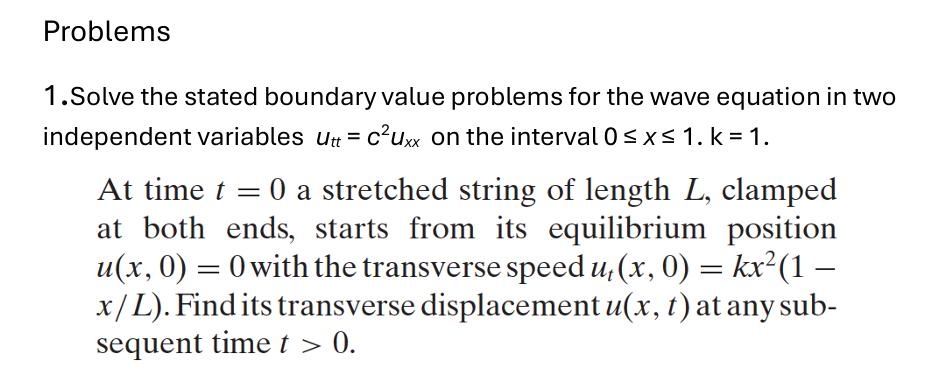

clf;
clearvars
% Parameters
L = 1; 
c = 1;
k = 1;
x = linspace(0, L, 100); % Spatial points
t = linspace(0, 5, 100); % Time points
u = zeros(length(x), length(t));
N = 70 

N = 70

**Fourier series solution**

for n = 1:N
    % Coefficient calculation 
    b_n = 2 * k * L^2 * (-1)^(n+1) / (n^3 * pi^3);
    for i = 1:length(x)
        for j = 1:length(t)
            u_n = b_n * sin(n * pi * x(i) / L) * cos(n * pi * c * t(j) / L);
            u(i, j) = u(i, j) + u_n;
        end
    end
end

**Plot graph 3D**

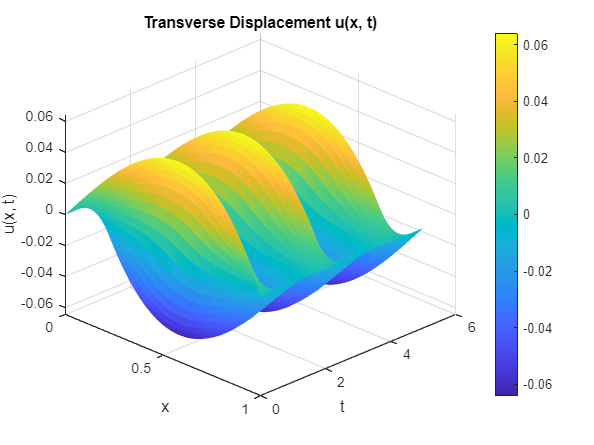

[X, T] = meshgrid(x, t);
surf(X, T, u', 'EdgeColor', 'none');
colorbar;
title('Transverse Displacement u(x, t)');
xlabel('x'); ylabel('t'); zlabel('u(x, t)');
grid on; view(45, 30);